# 9. Processing 3D NMR Spectrum

### Introduction

In our previous example, we delved into the realm of 3D NMR (Nuclear Magnetic Resonance) spectroscopy, emphasizing its critical role in the structural determination of large compounds, particularly for sizable proteins. The utility of 3D NMR becomes especially evident when dealing with complex molecular structures, where traditional 2D techniques might fall short in providing clear insights. In this example we go over the steps of processing the 3D spectra.

### **Experimental data import **

The 3D spectrum of GB1 has already been converted into a MATLAB matrix in the frequency spectrum and can be easily loaded in. The spectra has sizes 512x2048x805 corresponding to 15N x 13C x 1H  **[ F1  F2 F3 ]** . In a 3D NMR experiment, the direct dimension is typically designated as F3. This NMR data is kindly provided by Prof. Ilya Kuprov, University of Southampton.

% Load 3D HNCA GB1 spectrum
load('HNCA_GB1_Phase.mat','c_ax_ppm','h_ax_ppm','n_ax_ppm','data');

### **Phase correction**

In the previous example we showed how to visualize each peak with an interactive tool, when you view different peaks, you can notice that they are out of phase. We are able to correct this. In a similar manner to 2D NMR to apply manual phase correction we need to select a reference peak and apply phase correction individually to each dimension. However, in this case we would apply it to the three 1H, 13C,15N dimensions. By using the **Visualizing_HNCA.m. **we can select a peak to apply phase correction. We would need to isolate the 3D cube and as an example, lets pick a residue between 127-125ppm (15N), 8.78-8.58ppm (1H) and 48.5-47.6ppm (13C).

Let us extract the region of interest holding the reference peak as a 3D matrix. 

%  Pick a region of interest as reference for phase correction, with the
%  pick at the centre
F1_Region=   [127  125] ;
F3_Region = [8.78 8.58];
F2_Region = [48.5 47.6];

% Find the index from ppm values
F3_Region = findIndexFromPPM(h_ax_ppm',F3_Region);
F2_Region = findIndexFromPPM(c_ax_ppm',F2_Region);
F1_Region = findIndexFromPPM(n_ax_ppm',F1_Region');

% Extract the ppm values for each dimension
n_axis_region=n_ax_ppm(F1_Region(1):F1_Region(2));
h_axis_region=h_ax_ppm(F3_Region(1):F3_Region(2));
c_axis_region=c_ax_ppm(F2_Region(1):F2_Region(2));

% Extract a 3D region with our reference peak
region=data(F1_Region(1):F1_Region(2),F2_Region(1):F2_Region(2),F3_Region(1):F3_Region(2));

It is hard to visualize 3D cube of data, so let us view a 2D slice in the 1H-13C dimension at the midpoint of the 15N dimension. We have selected our regions, so the peak is roughly in the middle

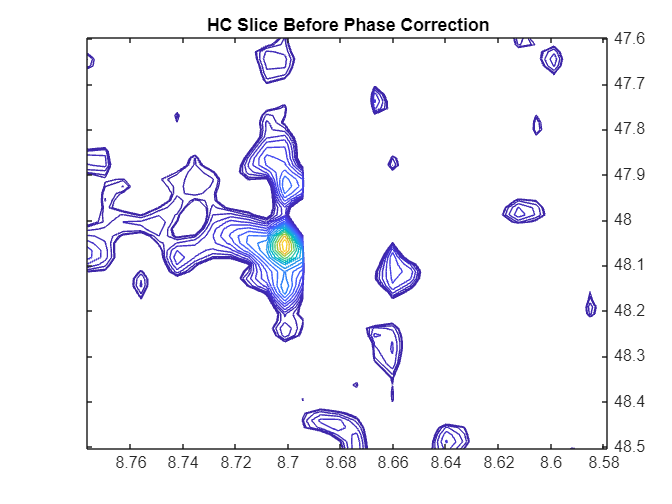

% Extract nitrogen slice. We take half way point assuming peak is centred
% in the cube
hc_slice=squeeze(region(floor(size(region,1)/2),:,:));

% Lets see what the 2D HC Slice region of interest looks like
figure()
smax=max(real(hc_slice),[],'all');
levels=0.95*smax*linspace(0,1,20).^2+0.05*smax;
contour(h_axis_region,c_axis_region,real(hc_slice),levels);
set(gca,'XDir','reverse','YDir','reverse','YAxisLocation','right')
title("HC Slice Before Phase Correction")
hold on;

On the right you can see the HC slice and it is obvious that phase correction is needed. Same as in 2D phase correction let us select an FID in one of the rows (1H) and one of the columns (13C). We pick column 15 and row 30 (roughly the middle of the cubes), since the peak is in the middle. Then we can interactively pick 0th and 1st order correction values.

% Apply phase correction in F3 (Hydrogen Dimension) in selected region
% [degrees] and store the values in memory
[F3_Final_PK0, F3_Final_PK1]=Set_Phase_Correction(hc_slice,30,'rows');

% Apply phase correction in F2 (Carbon Dimension) in selected region
% [degrees] and store the values in memory
[F2_Final_PK0, F2_Final_PK1]=Set_Phase_Correction(hc_slice,15,'columns');

We have phase corrected in the Carbon and the Hydrogen dimensions. Now let us correct the Nitrogen dimension. This can be achieved in the same way by extracting the 1H-15N dimension. You can see the HN slice on the right. The hydrogen dimension has already been phase corrected, but nitrogen is not, hence we can see a lot of dispersion. 

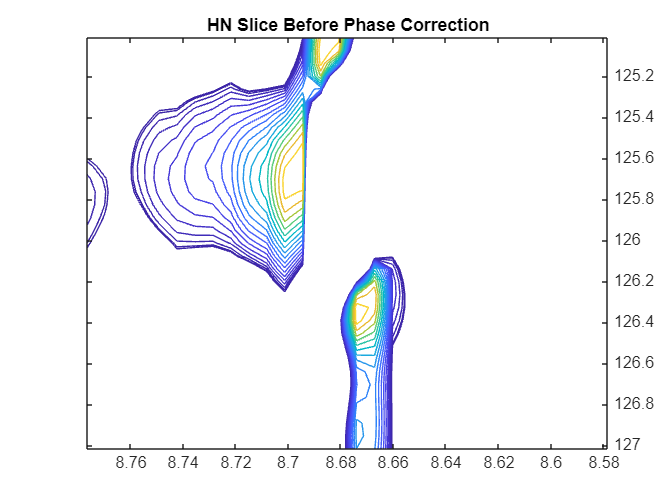

% Extract carbon slice
hn_slice=squeeze(region(:,floor(size(region,2)/2),:));

% Lets see HN Slice Before Phase Correction
figure()
smax=max(real(hn_slice),[],'all');
levels=0.95*smax*linspace(0,1,20).^2+0.05*smax;
contour(h_axis_region,n_axis_region,real(hn_slice),levels);
set(gca,'XDir','reverse','YDir','reverse','YAxisLocation','right')
title("HN Slice Before Phase Correction")
hold on;

We can interactively phase correct in the 15N dimensions by extracting an FID from the middle.

% Apply phase correction in F1 (Nitrogen) in selected region [degrees] and store the
% values in memory
[F1_Final_PK0, F1_Final_PK1]=Set_Phase_Correction(hn_slice,15,'columns');


We have selected our phase correction values for all three dimensions and we can apply it to the entire region of interest with a simple function.

% Apply Phase correction with aquired values to the entire section
corrected_spectrum = PhaseCorrection3D(F2_Final_PK0, F2_Final_PK1, region, 'F2');
corrected_spectrum = PhaseCorrection3D(F1_Final_PK0, F1_Final_PK1, corrected_spectrum, 'F1');
corrected_spectrum = PhaseCorrection3D(F3_Final_PK0, F3_Final_PK1, corrected_spectrum, 'F3');


Let us now see the impact of phase correction to the previously shown HC and HN slices of the reference peak. Clearly our peak is much more prominent.

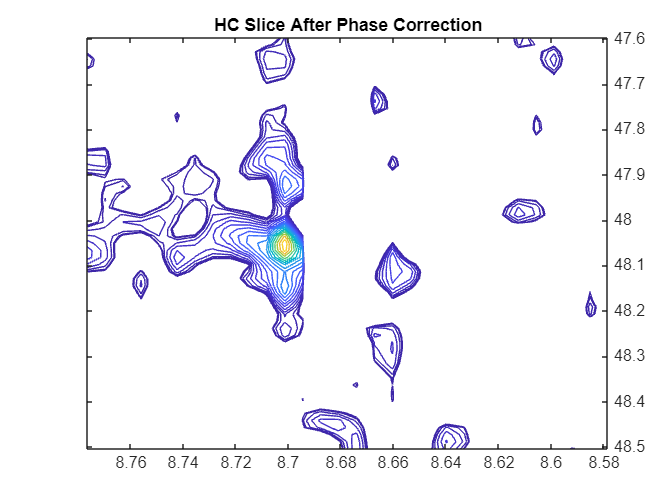

% Lets see what the 2D HC Slice region of interest  After Phase Correction
hc_slice=squeeze(corrected_spectrum(floor(size(corrected_spectrum,1)/2),:,:));

figure()
smax=max(real(hc_slice),[],'all');
levels=0.95*smax*linspace(0,1,20).^2+0.05*smax;
contour(h_axis_region,c_axis_region,real(hc_slice),levels);
set(gca,'XDir','reverse','YDir','reverse','YAxisLocation','right')
title("HC Slice After Phase Correction")
hold on;

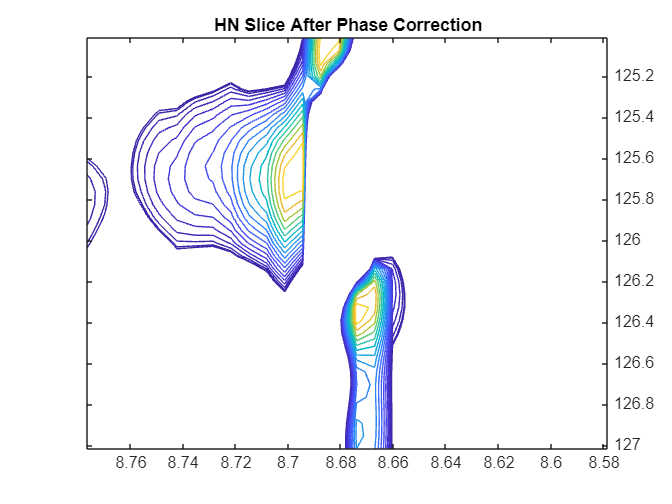


% Lets see what the 2D HN Slice region of interest Afer Phase Correction
hn_slice=squeeze(corrected_spectrum(:,floor(size(corrected_spectrum,2)/2),:));

figure()
smax=max(real(hn_slice),[],'all');
levels=0.95*smax*linspace(0,1,20).^2+0.05*smax;
contour(h_axis_region,n_axis_region,real(hn_slice),levels);
set(gca,'XDir','reverse','YDir','reverse','YAxisLocation','right')
title("HN Slice After Phase Correction")
hold on;

Confident in our phase correction values, we can apply it to the entire 3D spectrum with the same function PhaseCorrection3D, but now with the input of the entire 3D matrix holding the spectrum.

% Apply Phase correction with acquired values to the entire spectrum
signal = PhaseCorrection3D(F2_Final_PK0, F2_Final_PK1, data, 'F2');
signal = PhaseCorrection3D(F1_Final_PK0, F1_Final_PK1, signal, 'F1');
signal = PhaseCorrection3D(F3_Final_PK0, F3_Final_PK1, signal, 'F3');


Now that the entire spectrum is phase corrected and correctly processed with prominent peaks it is ready for the backbone assignment procedure. If we look at the 1H-13C slice of the selected peak we can now notice the shoulder peaks of the signal, these are representative for different amino types. These line shapes encode extra information for assignment.

### **Summary**

In this example we imported and processed 3D spectrum of a HNCA experiment on GB1. Phase correction was manually applied to all three dimensions interactively. The 0th and 1st order values were chosen by isolating a reference peak as a 3D cube of data and values chosen so that the 1D FID is correctly centered in all three dimensions. Visualizing 3D spectra is difficult, and this was achieved by extracting 2D slices at 1H-13C and 1H-15N dimensions. The impact of phase correction can be seen in these slices, especially in the shoulder peaks in the Carbon domain. These line shapes are dependent on amino acids generating these signals and can be used to assign each residue. 3D NMR plays a critical role in determining protein structure and dynamics. In this tutorial we processed the spectrum, so it is ready for further analysis and backbone assignment of the protein.

### **Utility functions**

function phaseCorrectedSignal=PhaseCorrection2D(phc0,phc1,signal,dimension)
    switch dimension
        case 'rows'
            numPoints=numel(signal(:,1));
            % Convert phase correction to radians
            phc0=deg2rad(phc0);

            % This multiplicity factor for 1st order correction
            phc1=deg2rad(phc1)/numPoints;         

            freq=linspace(1,numPoints,numPoints);

            % Apply the 0th and 1st order phase correction in F1
            phaseCorrection=exp(+1i*(phc0 + (phc1*freq')));
            phaseCorrectedSignal=signal.*phaseCorrection;
        case 'columns'
            numPoints=numel(signal(1,:));
            % Convert phase correction to radians
            phc0=deg2rad(phc0);
            phc1=deg2rad(phc1)/numPoints;   

            freq=linspace(1,numPoints,numPoints);

            % Apply the 0th and 1st order phase correction in F2
            phaseCorrection=exp(+1i*(phc0 + (phc1*freq')));
            phaseCorrectedSignal=signal.*phaseCorrection';
    end
end

function phaseCorrectedSignal=PhaseCorrection3D(phc0,phc1,signal,dimension)
    switch dimension
        case 'F3'
            numPoints=size(signal,3);
            % Convert phase correction to radians
            phc0=deg2rad(phc0);

            % This multiplicity factor for 1st order correction
            phc1=deg2rad(phc1)/numPoints;         
            
            freq=linspace(1,numPoints,numPoints);

            % Apply the 0th and 1st order phase correction in F1
            phaseCorrection=exp(+1i*(phc0 + (phc1*freq')));
            phaseCorrectedSignal=bsxfun(@times, signal, reshape(phaseCorrection, 1, 1, []));
            
        case 'F2'
            numPoints=size(signal,2);
            % Convert phase correction to radians
            phc0=deg2rad(phc0);
            phc1=deg2rad(phc1)/numPoints;   

            freq=linspace(1,numPoints,numPoints);

            % Apply the 0th and 1st order phase correction in F2
            phaseCorrection=exp(+1i*(phc0 + (phc1*freq')));
            phaseCorrectedSignal = bsxfun(@times, signal, reshape(phaseCorrection, 1, [], 1));
        case 'F1'
            numPoints=size(signal,1);
            % Convert phase correction to radians
            phc0=deg2rad(phc0);
            phc1=deg2rad(phc1)/numPoints;   

            freq=linspace(1,numPoints,numPoints);

            % Apply the 0th and 1st order phase correction in F2
            phaseCorrection=exp(+1i*(phc0 + (phc1*freq')));
            phaseCorrectedSignal = bsxfun(@times, signal, reshape(phaseCorrection,  [], 1, 1));
    end
end

function index=findIndexFromPPM(axis,region)

    % If region is a single value, convert it to a 1x2 matrix
    if numel(region) == 1
        differencesRg1 = abs(axis - region);
    else    
        % Calculate the absolute differences between the array elements and the target
        differencesRg1 = abs([axis - region(1);axis - region(2)]);
    end
   
    % Find the index of the minimum difference
    [~,index] = min(differencesRg1 ,[],2);
end

function [Final_PK0, Final_PK1]=Set_Phase_Correction(region,Peak,dimension)

    % Create a figure for plotting the spectrum before and after phase correction
    fig=figure();
    tiledlayout(2,1);

    switch dimension
        case 'columns'
            % Plot the initial spectrum before phase correction
            subplot(2, 1, 1);
            plot(real(region(:, Peak)));
            title(['Column ' num2str(Peak) ' before phase correction']);
        case 'rows'
            % Plot the initial spectrum before phase correction
            subplot(2, 1, 1);
            plot(real(region(Peak,:)));
            title(['Row ' num2str(Peak) ' before phase correction']);
    end

    % Create a button to increase the zeroth phase correction value
    PK0_Slider= uicontrol('style','slider','min',-360,'max',360,'val',0, ...
            'position',[10 10 300 30]);
    
    % Create a text label to display the zeroth order value
    PK0_Label = uicontrol('Style', 'text', 'Position', [100, 80, 200, 20],'String','PK0 Value : 0');
    
    % Create a button to increase the zeroth phase correction value
    PK1_Slider= uicontrol('style','slider','min',-360,'max',360,'val',0, ...
            'position',[2200 10 300 30]);
    
    % Create a text label to display the zeroth order value
    PK1_Label = uicontrol('Style', 'text', 'Position', [2200, 80, 200, 20],'String','PK1 Value : 0');
      
    set(PK0_Slider, 'CallBack', {@incrementValue, region,PK0_Slider,PK0_Label,PK1_Slider,PK1_Label,Peak,dimension});
    set(PK1_Slider, 'CallBack', {@incrementValue, region,PK0_Slider,PK0_Label,PK1_Slider,PK1_Label,Peak,dimension});


      % Set close function to capture final values before closing the figure
    set(fig, 'CloseRequestFcn', @closeFigure);

    % Function to capture final values before closing
    function closeFigure(~, ~)
        Final_PK0 = PK0_Slider.Value;
        Final_PK1 = PK1_Slider.Value;
        delete(fig); % Close the figure
    end

    % Wait for the figure to be deleted (closed)
    waitfor(fig);
end

% Function to increment the phase correction value and update the plot
function incrementValue(~, ~,region,PK0_Slider,PK0_Label,PK1_Slider,PK1_Label,Peak,dimension)

    PK_0 = PK0_Slider.Value;
    PK_1= PK1_Slider.Value;
   
    set(PK0_Label, 'String', ['PK0 Value: ', num2str(PK_0)]); % Update the PK0 label
    set(PK1_Label, 'String', ['PK1 Value: ', num2str(PK_1)]); % Update the PK1 label
    
    switch dimension
        case 'columns'
            corrected_spectrum = PhaseCorrection2D(PK_0, PK_1, region, 'columns');
            subplot(2, 1, 2);
            plot(real(corrected_spectrum(:, Peak)));
            title(['Column ' num2str(Peak) ' after phase correction']);
        case 'rows'
            corrected_spectrum = PhaseCorrection2D(PK_0, PK_1, region, 'rows');
            subplot(2, 1, 2);
            plot(real(corrected_spectrum(Peak,:)));
            title(['Row ' num2str(Peak) ' after phase correction']);
    end


end